# Carbon Steel Properties: Interpolation, Curve-Fit and Regression

In this exercise you will use interpolation, polynomial curve-fitting and nonlinear regression to describe experimental stress-strain data.  The objective is to demonstrate these tools for augmenting data and to create underyling models to describe and predict the behavior.

## The Data

In class during week 2 we were woking with basic plotting and with array (element-wise) artithmetic.  One of the demonstrations presented was used the following experimental stress-strain data for carbon steel

% Strain [mm/mm]
strain_exp = [0, 0.0024, 0.003749347, 0.005234888, ...
    0.007631515, 0.011446096, 0.017384888, ...
    0.026405375, 0.039775799];
% Stress [MPa]
stress_exp = [0, 500, 550, 600, 660, 720, 780, 840, 900];

Which we plotted like this...

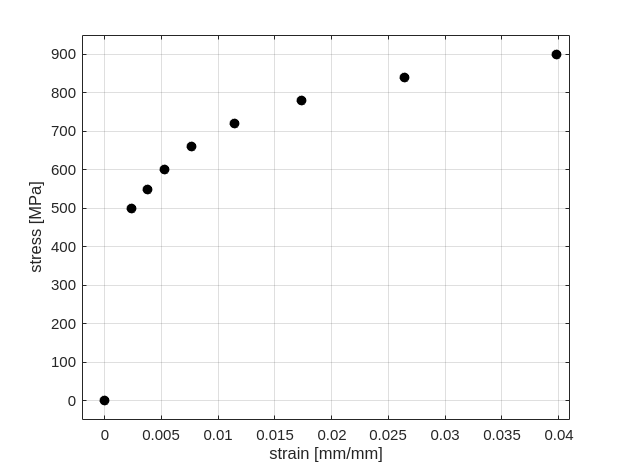

figure;
clf()
plot(strain_exp, stress_exp, 'ko', "MarkerFaceColor", "k", "DisplayName", "Data")
axis([-0.002, 0.041, -50, 950])
xlabel('strain [mm/mm]');
ylabel('stress [MPa]')
grid('on')

## Interpolation

There are quite a few data points, but the data only provides strain at specific values of stress.  Use linear interpolation to predict the strain (deflection) of the steel for the following values of stress: 200, 755 and 890 MPa.

new_stress = [200, 755, 890];
new_strain = interp1(stress_exp, strain_exp, new_stress); 

Add the three new points to the figure to verify that they are sane.

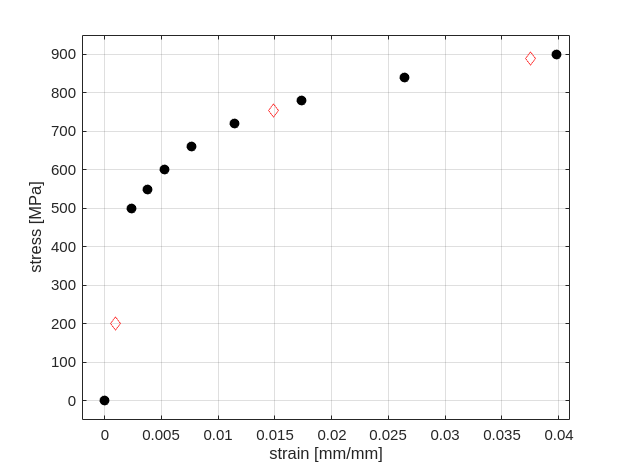

hold on;
plot(new_strain, new_stress, 'rd', "DisplayName","interp1")

legend('Location','northwest')

## Polynomial Curve-Fit

degree = 4;
[p, S]  = polyfit(strain_exp, stress_exp, degree)

p = 1.0e+09 *

   -6.2958    0.5359   -0.0152    0.0002    0.0000


S = struct with fields:
           R: [5×5 double]
          df: 4
       normr: 151.5959
    rsquared: 0.9595


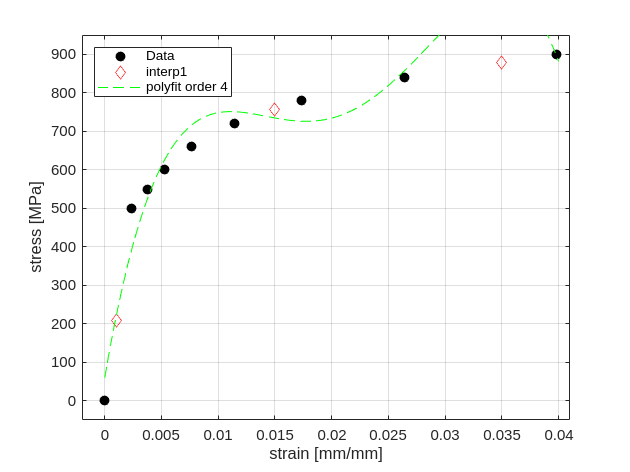

strain_fit = linspace(0, 0.04, 100);
stress_fit = polyval(p, strain_fit);
plot(strain_fit, stress_fit, 'g--', "DisplayName", sprintf("polyfit order %d", degree))

Ramberg-Osgood Equation

Fit of the experimental data.

function strain = ramberg(params, stress)
    n = params(1);
    K = params(2);
    E = 210000;   % MPa
    strain = stress/E + (stress/K).^n;
end
params0 = [5, 1000];
params_reg = nlinfit(stress_exp, strain_exp, @ramberg, params0)

params_reg = 1.0e+03 *

    0.0067    1.4802


fprintf("Ramberg-Osgood nonlinear regression\n " + ...
    "K = %.1f \n n = %.3f", params_reg(2), params_reg(1));

Ramberg-Osgood nonlinear regression
 K = 1480.2 
 n = 6.708


stress_reg = linspace(stress_exp(1), stress_exp(end), 100)'

stress_reg =          0
    9.0909
   18.1818
   27.2727
   36.3636
   45.4545
   54.5455
   63.6364
   72.7273
   81.8182


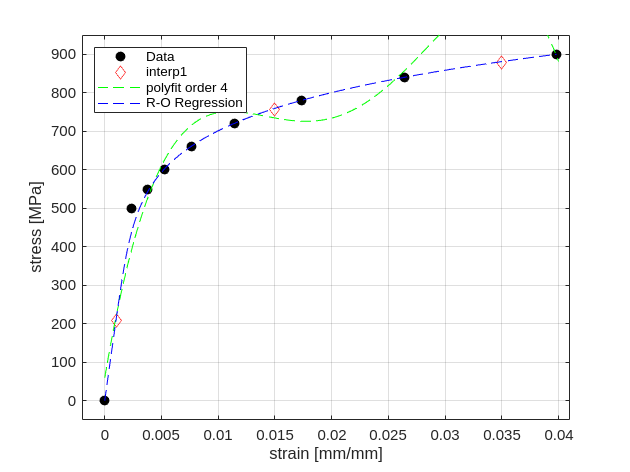

strain_reg = ramberg(params_reg, stress_reg);
plot(strain_reg, stress_reg, 'b--', "DisplayName","R-O Regression")